clear all
syms a1 a2 a3 b1 b2 b3 c1 c2 c3 t

l2 = 2.5

l2 = 2.5000

l3 = 10

l3 = 10

h = 2

h = 2


vars = [a1, a2, a3, b1, b2, b3, c1, c2, c3]

$$vars = \left(\begin{array}{ccccccccc} a_{1} & a_{2} & a_{3} & b_{1} & b_{2} & b_{3} & c_{1} & c_{2} & c_{3} \end{array}\right)$$

constraints = [a1; a2; a1+l2*cos(a3)-b1; a2+l2*sin(a3)-b2; b1+l3*cos(b3)-c1; b2+l3*sin(b3)-c2; c2-h; c3; a3-40*pi*t]

$$constraints = \left(\begin{array}{c} a_{1}\\ a_{2}\\ a_{1}-b_{1}+\frac{5\,\cos\left(a_{3}\right)}{2}\\ a_{2}-b_{2}+\frac{5\,\sin\left(a_{3}\right)}{2}\\ b_{1}-c_{1}+10\,\cos\left(b_{3}\right)\\ b_{2}-c_{2}+10\,\sin\left(b_{3}\right)\\ c_{2}-2\\ c_{3}\\ a_{3}-40\,\pi \,t \end{array}\right)$$

% xi+1 = xi - inv(f'(xi))*f(xi)
x0 = [0; 0; 0; 2.5; 0; asin(0.2); 2.5+(96)^0.5; 2; 0]

x0 =          0
         0
         0
    2.5000
         0
    0.2014
   12.2980
    2.0000
         0


m = subs(constraints,t,0)

$$m = \left(\begin{array}{c} a_{1}\\ a_{2}\\ a_{1}-b_{1}+\frac{5\,\cos\left(a_{3}\right)}{2}\\ a_{2}-b_{2}+\frac{5\,\sin\left(a_{3}\right)}{2}\\ b_{1}-c_{1}+10\,\cos\left(b_{3}\right)\\ b_{2}-c_{2}+10\,\sin\left(b_{3}\right)\\ c_{2}-2\\ c_{3}\\ a_{3} \end{array}\right)$$

x_prev = x0;
result = [];
duration = 0.01:0.001:0.1;

for time = duration
    while 1
        C      = subs(constraints, t, time);
        dx     = - double( subs(jacobian(C), vars, x_prev')\subs(C, vars, x_prev') );
        x      = x_prev + dx;
        x_prev = x;

        if (dx < 0.05)
            break
        end
    end
    result = [result;x(3)];
end

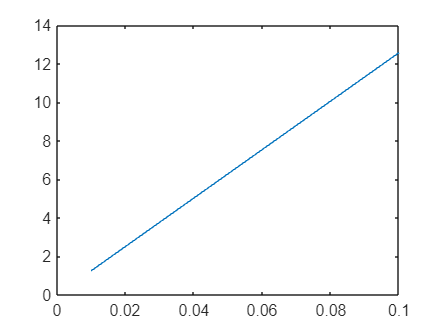

plot(duration,result)